Reading in data

clear
imread("data32\test\animal animal_faces cat cat_face\0BGPHALKEI6K.jpg", "jpg")

ans = 32×32×3 uint8 array
ans(:,:,1) =

   164   171   166   159   159   150   150   145   137   140   117    76    61    72    84    86    90    90    90    88    89    87    87    89    88    90    88    87    84    76    77    72
   170   172   169   158   159   155   150   143   140   141   116    75    59    71    83    86    87    88    89    88    90    92    92    88    90    93    92    86    84    82    79    71
   152   173   172   164   157   150   148   141   137   139   114    76    62    71    80    82    81    80    86    92    92    88    90    93    90    88    82    83    80    83    69    71
   150   172   165   160   156   151   146   142   136   140   116    76    62    72    79    82    80    80    85    89    90    95    95    87    85    88    81    80    76    72    72    70
   149   169   167   158   156   147   139   138   135   140   118    76    60    71    81    83    79    82    85    89    91    92    90    86    81    76    87   137   136    74    65  


imagefiles = dir("data32\test\animal animal_faces cat cat_face\*.jpg")

imagefiles = 1661×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


filepath = "data32\test\animal animal_faces cat cat_face"

filepath = "data32\test\animal animal_faces cat cat_face"

for ii=1:200
   currentfilename = imagefiles(ii).name;
   currentimage = im2double(imread(filepath + "\" +  currentfilename));
   images{ii} = currentimage;
end

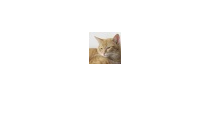

imshow(images{1})

Reproduce image

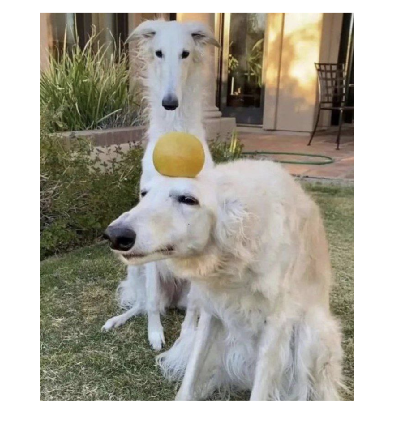

targetImage = im2double(imread("dogdogorange.png"));

imshow(targetImage)


[l, h, d] = size(targetImage)

l = 867

h = 701

d = 3

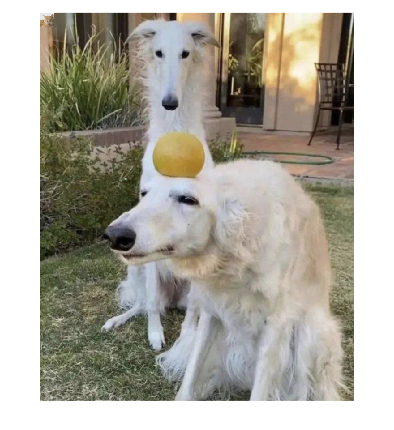


targetImage(1:32, 1:32, :) = images{1};

imshow(targetImage)

Image Segmentation

Use kmeans with random clustters to segment the image 

% segmentedImage = im2double(targetImage)
% for i = 1:3
% segmentedImage(:,:,i) = segmentImage(segmentedImage(:,:,i));
% end
% 
% imshow(segmentedImage)

load("xyz.mat")
load("illum.mat")
load("DLP.mat")
k = 100 ./ sum(xyz(:,2)' .* CIED65)

k = 4.6460


load("M_XYZ2RGB.mat")


Big Loop

rTileSize = 32;
oTileSize = 8;
%[~, datasetSize] = size(images)
[rows, cols, ~] = size(targetImage)

rows = 867

cols = 701

tileRows = ceil(rows / oTileSize)

tileRows = 109

tileCols = ceil(cols / oTileSize)

tileCols = 88


outputImage = zeros(tileRows*rTileSize, tileCols * rTileSize,3);

%preprocess images by removing very similiar ones. Uses given threshold
%value
processedImages = preprocessImages(images, 12);

clear("images") %jaja overwrite

[~, datasetSize] = size(processedImages)

datasetSize = 131

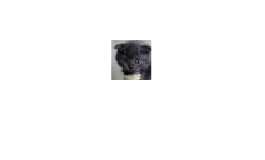


imshow(processedImages{2})

processedImages

processedImages = 1×131 cell array
    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {32×32×3 double}    {

processbar = waitbar(0, 'Processing Images...');
% go through each tile
for c = 1:tileCols
    for r = 1:tileRows
        tileRFrom = 1 + (r-1)*(oTileSize);
        tileRTo = r*oTileSize;
        if tileRTo > rows
            tileRTo = rows;
        end
        tileCFrom = 1 + (c-1)*(oTileSize);
        tileCTo = c*oTileSize;
        if tileCTo > cols
            tileCTo = cols;
        end
        currentTile = targetImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :);

        % convert current Tile to xyz, might use average colour
        averageTileXYZ = averageColourXYZ(currentTile);
        
        %meanRGB(1) = mean(mean(currentTile(:,:,1)));
        %meanRGB(2) = mean(mean(currentTile(:,:,2)));
        %meanRGB(3) = mean(mean(currentTile(:,:,3)));
        
        %Srgb = DLP * meanRGB';
        
        %k = 100 ./ sum(xyz(:,2)' .* CIED65);
        
        %colourXYZ = (k * xyz' * Srgb);

        %a = inv(M_XYZ2RGB) * meanRGB'

        %imshow(currentTile)
        
        bestImageIndex = 0;
        bestDeltaE = 1000;

        waitbar(c/tileCols, processbar, "bonking kitties...");

        % find best image for each tile
        for i = 1:datasetSize
            
            curImg = processedImages{i};
            % convert current sample image to xyz

            %imshow(curImg)

            currentImageXYZ = averageColourXYZ(curImg);

            % use calcDeltaE
            [meanDeltaE, Max] = calcDeltaE(averageTileXYZ', currentImageXYZ');


            if Max < bestDeltaE
                bestDeltaE = Max;
                bestImageIndex = i;
            end


            averageTileXYZ;
            currentImageXYZ;
            Max;
            i;
            bestImageIndex;

        end
        tileRFrom = 1 + (r-1)*(rTileSize);
        tileRTo = r*rTileSize;
        tileCFrom = 1 + (c-1)*(rTileSize);
        tileCTo = c*rTileSize;
        outputImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :) = processedImages{bestImageIndex};
    end
end

Error using waitbar (line 101)
The second argument must be a message character vector or a handle to an existing waitbar.


close(h)

imshow(outputImage)

Segment image into 32 bit chunks and standard deviate colours

function output = segmentImage(img)
img = im2double(img);

blockSize = [32, 32]; % går att byta
output = blockproc(img, blockSize, @processBlock);

end

%skum dokumentation
function outBlock = processBlock(blockStruct)
    originalBlock = blockStruct.data;
        stdValue = std2(originalBlock);
        outBlock = stdValue * ones(size(originalBlock), 'like', originalBlock);
end